# 例1.6（復元処理）

村松正吾　「多次元信号・画像処理の基礎と展開」

動作確認： MATLAB R2017a

## 画像データのダウンロード

% utilities.download_img

## 画像データの読込

X = im2double(rgb2gray(imread('./data/lena.png')));

## 劣化前の画像表示

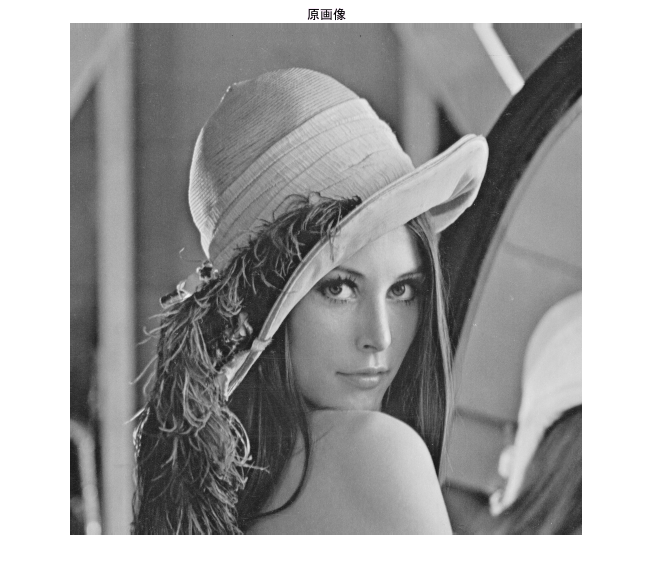

figure(1)
imshow(X)
title('原画像')

## 劣化過程

hsigma  = 4;                    % ガウスカーネル分散
hsize   = 2*ceil(2*hsigma)+1;   % ガウスカーネルサイズ
nvar    = (10/255)^2;            % 加法性白色ガウスノイズ分散
gaussfilt = fspecial('gaussian',hsize,hsigma);             % ガウスカーネル
linproc = @(x) imfilter(x,gaussfilt,'conv','circular'); % 線形観測過程
U = linproc(X);                 % 線形観測
V = imnoise(U,'gaussian',0,nvar);  % 加法性白色ガウスノイズ

## 劣化後の画像表示

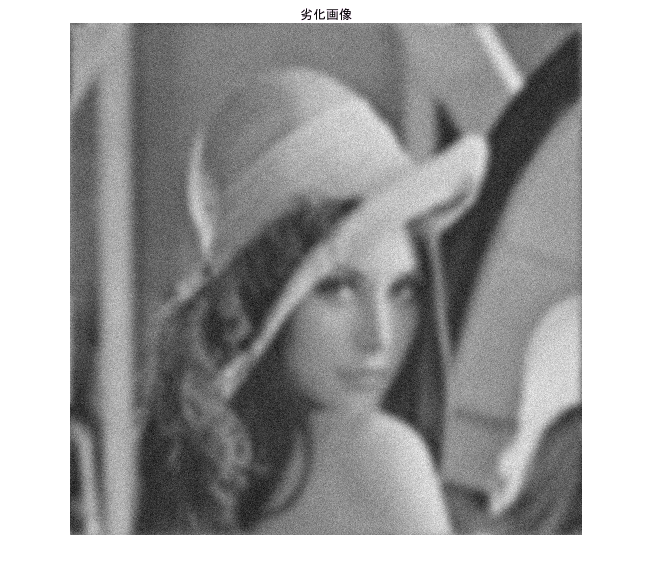

figure(2)
imshow(V)
title('劣化画像')

## 劣化後の品質

fprintf('劣化後の品質(PSNR)： %6.2f [dB]\n',psnr(V,X))

劣化後の品質(PSNR)：  23.12 [dB]


## 復元前処理

adjproc = @(x) imfilter(x,gaussfilt,'corr','circular'); %　随伴観測過程
vpst = ones(size(V),'like',V);
lpre = 1.0;
err_ = Inf;
while ( err_ >  1e-10 ) % Power method
    % vpst = (P.'*P)*vupre
    vpre = vpst/norm(vpst(:));
    u    = linproc(vpre); % P
    vpst = adjproc(u);    % P.'
    n    = (vpst(:).'*vpst(:));
    d    = (vpst(:).'*vpre(:));
    lpst = n/d;
    err_ = norm(lpst-lpre)^2;
    lpre = lpst;
end
frameBound = 1; % フレーム境界
L = frameBound*lpst ;  
%fprintf('L = %g\n',L);

## **復元処理(FISTA)**

lambda  = 0.01;
nIter   = 20;
nLevels = 5;
wname   = 'haar';
isFista = true;
%
Wpre = swt2(adjproc(V),nLevels,wname);
C = Wpre;
tpre = 1;
for itr = 1:nIter
    R = linproc(iswt2(C,wname))-V;
    D = (1/L)*swt2(adjproc(R),nLevels,wname);
    W = softthresh(C-D,lambda/L);
    if isFista
        t = (1+sqrt(1+4*tpre^2))/2;
        C = W+(tpre-1)/t*(W-Wpre);
        tpre = t;
        Wpre = W;
    else
        C = W;
    end
end
Y = iswt2(C,wname);

## 復元後の画像表示

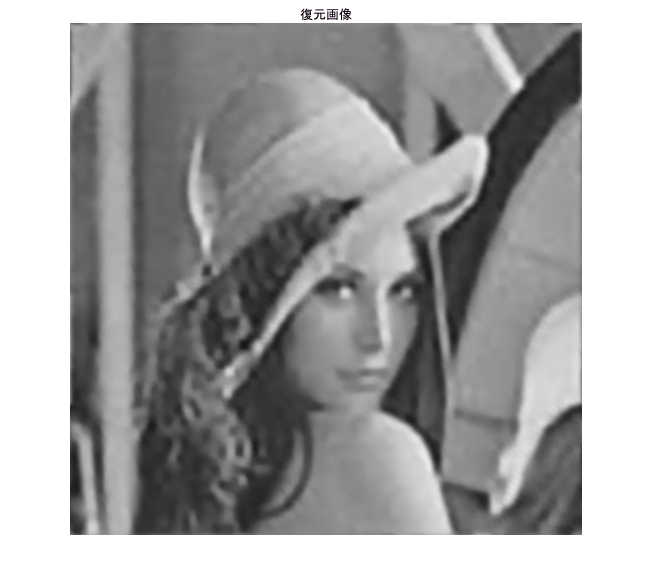

figure(3)
imshow(Y)
title('復元画像')

## 復元後の品質

fprintf('復元後の品質(PSNR)： %6.2f [dB]\n',psnr(Y,X))

復元後の品質(PSNR)：  26.36 [dB]


## 関数定義

ソフト閾値処理

function y = softthresh(x,thresh)
    v = abs(x)-thresh;
    y = sign(x).*(v+abs(v))/2;
end
